Q1

n=[7,12];
for i=1:2
    A=hilb(n(i));
    [Q1,R1]=cgsqr(A);
    [Q2,R2]=mgsqr(A);
    [Q3,R3]=qr(A,0);
    fprintf('n=%d\n',n(i));
    norm1=norm(Q1'*Q1-eye(n(i)),2);
    norm2=norm(Q2'*Q2-eye(n(i)),2);
    norm3=norm(A-Q3*R3,2);
    fprintf('||Q1^TQ1-I||=%e\n',norm1);
    fprintf('||Q2^TQ2-I||=%e\n',norm2);
    fprintf('||H-Q*R||=%e\n',norm3);
    fprintf('u*cond(A)=%e\n',eps*cond(A));
end

n=7


||Q1^TQ1-I||=2.966837e-01


||Q2^TQ2-I||=3.829058e-09


||H-Q*R||=6.629986e-16


u*cond(A)=1.055528e-07


n=12


||Q1^TQ1-I||=4.686256e+00


||Q2^TQ2-I||=1.051926e-01


||H-Q*R||=3.782171e-16


u*cond(A)=3.793900e+00


Q2

[U,X]=qr(randn(80));
[V,X]=qr(randn(80));
S=diag(2.^(-1:-1:-80));
A=U*S*V';
[QC,RC]=cgsqr(A);
[QM,RM]=mgsqr(A);
[Q,R]=qr(A);
fprintf('||QC^t*QC-I||=%e\n',norm(QC'*QC-eye(80)));

||QC^t*QC-I||=5.326970e+01


fprintf('||QM^t*QM-I||=%e\n',norm(QM'*QM-eye(80)));

||QM^t*QM-I||=9.990263e-01


fprintf('||Q^t*Q-I||=%e\n',norm(Q'*Q-eye(80)));

||Q^t*Q-I||=2.943423e-15


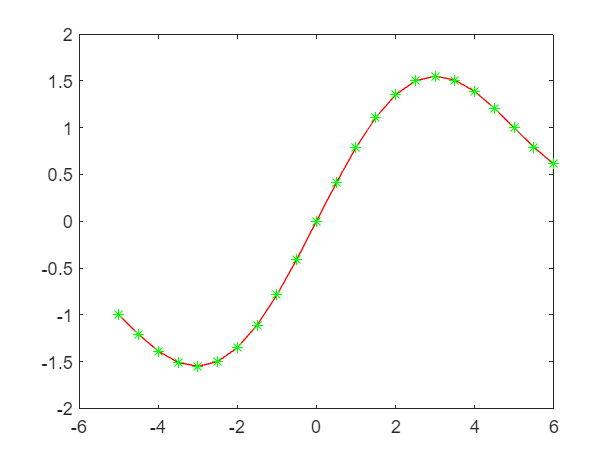

 x= (1:80);
 hold off

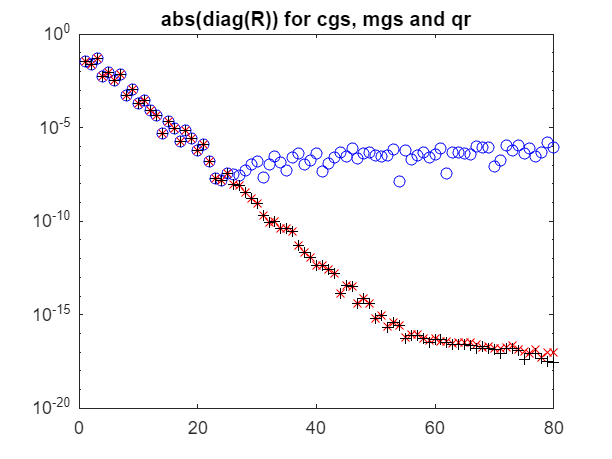

 semilogy(x, abs(diag( RC ) ), 'bo')
 hold on
 semilogy(x, abs(diag( RM ) ), 'rx')
 semilogy(x, abs(diag( R ) ), 'k+')
 title('abs(diag(R)) for cgs, mgs and qr')
 % gtext('cgs=o, mgs = x, qr=+')
 hold off;

Q3(a)

 f=@(x) (sin(pi.*x/5)+x/5);
 t=(-5:0.5:6)';
 b=f(t);
 A=t.^(0:5);
 [Q,R]=cgsqr([A b]);
 x=R(1:6,1:6)\R(1:6,7);
 % disp(x)
 res=norm(R(7:end,7));
 disp(res);

    0.0672



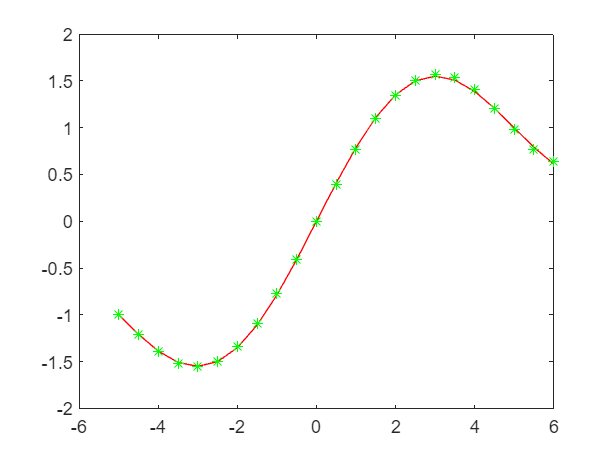

 plot(t,b,'r-')
 hold on ;
 plot(t,polyval(flipud(x),t),'g*')
 hold off;

 A=t.^(0:18);
 [Q,R]=cgsqr([A b]);
 x=R(1:19,1:19)\R(1:19,20);
 % disp(x)
 res=norm(R(19:end,19));
 disp(res);

   8.1621e+07



 plot(t,b,'r-')
 hold on ;
 plot(t,polyval(flipud(x),t),'g*')
 hold off;

Q3(b)

 f=@(x) (sin(pi.*x/5)+x/5);
 t=(-5:0.5:6)';
 b=f(t);
 A=t.^(0:5);
 [Q,R]=mgsqr([A b]);
 x=R(1:6,1:6)\R(1:6,7);
 % disp(x)
 res=norm(R(7:end,7));
 disp(res);

    0.0672



 plot(t,b,'r-')
 hold on ;
 plot(t,polyval(flipud(x),t),'g*')
 hold off;

 A=t.^(0:18);
 [Q,R]=mgsqr([A b]);
 x=R(1:19,1:19)\R(1:19,20);
 % disp(x)
 res=norm(R(19:end,19));
 disp(res);

   8.1586e+07



 plot(t,b,'r-')
 hold on ;
 plot(t,polyval(flipud(x),t),'g*')
 hold off;

Q3(c)

 f=@(x) (sin(pi.*x/5)+x/5);
 t=(-5:0.5:6)';
 b=f(t);
 A=t.^(0:5);
 [Q,R]=qr([A b]);
 x=R(1:6,1:6)\R(1:6,7);
 % disp(x)
 res=norm(R(7:end,7));
 disp(res);

    0.0672



 plot(t,b,'r-')
 hold on ;
 plot(t,polyval(flipud(x),t),'g*')
 hold off;

 A=t.^(0:18);
 [Q,R]=qr([A b]);
 x=R(1:19,1:19)\R(1:19,20);
 % disp(x)
 res=norm(R(19:end,19));
 disp(res);

   8.1586e+07



 plot(t,b,'r-')
 hold on ;
 plot(t,polyval(flipud(x),t),'g*')
 hold off;

function [Q,R]=cgsqr(A)
    [~,n]=size(A);
    Q=A;
    R=zeros(n,n);
    for k=1:n
        R(1:k-1,k)=Q(:,1:k-1)'*A(:,k);
        Q(:,k)=A(:,k)-Q(:,1:k-1)*R(1:k-1,k);
        R(k,k)=norm(Q(:,k));
        Q(:,k)=Q(:,k)/R(k,k);
    end
end

function [Q,R]=mgsqr(A)
    [~,n]=size(A);
    Q=A;
    R=zeros(n,n);
    for k=1:n
        R(k,k)=norm(Q(:,k));
        Q(:,k)=Q(:,k)/R(k,k);
        R(k,k+1:n)=Q(:,k)'*Q(:,k+1:n);
        Q(:,k+1:n)=Q(:,k+1:n)-Q(:,k)*R(k,k+1:n);
    end
end